clc;clear;

**For functinality simple test**

% Load dataset
[trainX, trainY, testX, testY] = dataload(1);

% One step functionality test for tree generation
cartree = tree_train(trainX, trainY, 1, false);
out = tree_predict(testX, cartree);
acc = sum(out==testY)/size(testX, 1)

acc = 0.5921

% One step functionality test for tree pruning
% TODO: Current effect is not good, use CART pruning to improve it(Use validation dataset)
cartree = tree_train(trainX, trainY, 1, true);
out = tree_predict(testX, cartree);
acc = sum(out==testY)/size(testX, 1)

acc = 0.5335

% One step functionality test for RF
nTree = 10;
     
RF = cell(nTree);
for tree=1:nTree
    % Sample without deletion(Bagging sampling)
    bagging_idx = ceil(rand(size(trainX, 1), 1)*size(trainX, 1));
    % Train tree
    dt = tree_train(trainX(bagging_idx, :), trainY(bagging_idx, :), 1, false);
    RF{tree} = dt;
end

% Testing
output = zeros(size(testX, 1), nTree);
for tree=1:nTree
    output(:, tree) = tree_predict(testX, RF{tree});
end
% Choose the mode one as result of classification
result = mode(output, 2);
acc = sum(result==testY)/size(testX, 1)

acc = 0.6148

**For comparison among full tree, tree with pruning and 10-tree RF**

% Generation 10
outcome = [];
for i=1:10
    [trainX, trainY, testX, testY] = dataload(i);
    cartree = tree_train(trainX, trainY, 1);
    out = tree_predict(testX, cartree);
    acc = sum(out==testY)/size(testX, 1);
    outcome = [outcome; acc];
end
roundn(outcome, -4)

ans =     0.5945
    0.8796
    0.9653
    0.8216
    0.9272
    0.9750
    0.5085
    0.9697
    0.6950
    0.8918


% RF-10-trees 10
nTree = 10;
outcome = [];
for i=1:10
    % Load dataset
    [trainX, trainY, testX, testY] = dataload(i);
    
    % RF training
    RF = cell(nTree);
    for tree=1:nTree
        % Sample without deletion
        bagging_idx = ceil(rand(size(trainX, 1), 1)*size(trainX, 1));
        % Train tree
        dt = tree_train(trainX(bagging_idx, :), trainY(bagging_idx, :), 1, false);
        RF{tree} = dt;
    end
    
    output = zeros(size(testX, 1), nTree);
    for tree=1:nTree
        output(:, tree) = tree_predict(testX, RF{tree});
    end
    result = mode(output, 2);
    acc = sum(result==testY)/size(testX, 1);
    outcome = [outcome; acc];
end

ans =     0.6292
    0.8994
    0.9624
    0.8709
    0.9484
    0.9859
    0.5627
    0.9719
    0.7100
    0.9436


roundn(outcome, -4)

% RF for different number of trees
ntree_set = 10:10:100;
nTree = 10;
outcome = [];

% The most complex dataset
[trainX, trainY, testX, testY] = dataload(10);

for i=1:length(ntree_set)
    nTree = ntree_set(i);
    res = [];
    RF = cell(nTree);
    for j = 1:10
        for tree=1:nTree
            % Sample without deletion(Bagging sampling)
            bagging_idx = ceil(rand(size(trainX, 1), 1)*size(trainX, 1));
            % Train tree
            dt = tree_train(trainX(bagging_idx, :), trainY(bagging_idx, :), 1, false);
            RF{tree} = dt;
        end
        
        % Testing
        output = zeros(size(testX, 1), nTree);
        for tree=1:nTree
            output(:, tree) = tree_predict(testX, RF{tree});
        end
        % Choose the mode one as result of classification
        result = mode(output, 2);
        res(j) = sum(result==testY)/size(testX, 1);
    end
    outcome(i) = mean(res);
end
roundn(outcome, -4)

% RF with different features
nTree = 40;
nFeature = 7;
[trainX, trainY, testX, testY] = dataload(4);

RF = cell(nTree);
Features = cell(nTree);
for tree=1:nTree
    % Sample without deletion(Bagging sampling)
    bagging_idx = ceil(rand(size(trainX, 1), 1)*size(trainX, 1));
    feature_sel = sort(randperm(size(trainX, 2), nFeature));
    Features{tree} = feature_sel;
    % Train tree
    trainX_sel = trainX(:, feature_sel);
    dt = tree_train(trainX_sel(bagging_idx, :), trainY(bagging_idx, :), 1, false);
    RF{tree} = dt;
end

% Testing
output = zeros(size(testX, 1), nTree);
for tree=1:nTree
    testX_sel = testX(:, Features{tree});
    output(:, tree) = tree_predict(testX, RF{tree});
end
% Choose the mode one as result of classification
result = mode(output, 2);
acc = sum(result==testY)/size(testX, 1)

acc = 0.5742

% RF 10
outcome = [];
nTree_set = 10:10:100;
for i=4:4
    for n=1:10
    nTree = nTree_set(n);
    [trainX, trainY, testX, testY] = dataload(i);
    RF = cell(nTree);
    for tree=1:nTree
        % Sample without deletion
        bagging_idx = ceil(rand(size(trainX, 1), 1)*size(trainX, 1));
        % Set aside 1/10 for validation
        interval = ceil(size(trainX, 1)/10);
        validate_subset_X = trainX(bagging_idx(1:interval), :);
        validate_subset_Y = trainY(bagging_idx(1:interval), :);
        train_subset_X = trainX(bagging_idx(interval+1:end), :);
        train_subset_Y = trainY(bagging_idx(interval+1:end), :);
        % Train tree
        dt = tree_train(trainX(bagging_idx, :), trainY(bagging_idx, :), 1, false);
%         dt = tree_train(train_subset_X, train_subset_Y, 1);
%         dt = tree_prune(dt, 1, validate_subset_X, validate_subset_Y);
        RF{tree} = dt;
    end
    output = zeros(size(testX, 1), nTree);
    for tree=1:nTree
        output(:, tree) = tree_predict(testX, RF{tree});
    end
    result = mode(output, 2);
    acc = sum(result==testY)/size(testX, 1);
    outcome = [outcome; acc];
    end
end
roundn(outcome, -4)

ans =     0.8474
    0.8568
    0.8592
    0.8615
    0.8592
    0.8521
    0.8662
    0.8756
    0.8685
    0.8662


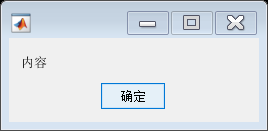

msgbox({'内容'})

% RF 10 4-fold
outcome = [];
nTree = 10;
k_cross = 10;
for i=1:10
    val_acc = zeros(k_cross,1);   % Initialisation
    tree_save = cell(k_cross, 1);
    
    [trainX, trainY, testX, testY] = dataload(i);
    cv_part = cvpartition(trainY,'KFold',k_cross);    % Create indices for training/validation subsets
    
    for k = 1: k_cross
        % Collect training/validation sets
        val_trainX = trainX(cv_part.training(k),:);
        val_trainY = trainY(cv_part.training(k),:);
        val_testX = trainX(cv_part.test(k),:);
        val_testY = trainY(cv_part.test(k),:);
        
        RF = cell(nTree, 1);
        for tree=1:nTree
            % Sample without deletion
            bagging_idx = ceil(rand(size(val_trainX, 1), 1)*size(val_trainX, 1));
            % Train tree
            dt = tree_train(val_trainX(bagging_idx, :), val_trainY(bagging_idx, :), 1, false);
            RF{tree} = dt;
        end
        
        % Testing
        output = zeros(size(val_testX, 1), nTree);
        for tree=1:nTree
            output(:, tree) = tree_predict(val_testX, RF{tree});
        end
        result = mode(output, 2);
        acc = sum(result==val_testY)/size(val_testX, 1);
        val_acc(k) = acc;
        tree_save{k} = RF;
    end
    [max_valacc, idx] = max(val_acc);
    RF = tree_save{idx};
    output = zeros(size(testX, 1), nTree);
    for tree=1:nTree
        output(:, tree) = tree_predict(testX, RF{tree});
    end
    result = mode(output, 2);
    acc = sum(result==testY)/size(testX, 1);
    outcome = [outcome; acc];
end
roundn(outcome, -4)
msgbox({'内容'})

**Function codes**

% Tree prune(independent)
% TODO: May be given up due to merge into the process of generation

function dt = tree_prune(tree, node, testX, testY)
    persistent cartree alpha
    if node == 1
        alpha = 0.05;
        cartree = tree;
    end
    left = cartree(node, 5);
    right = cartree(node, 6);
    if cartree(left, 2) == 1
        tree_prune(cartree, left, testX, testY)
    end
    if cartree(right, 2) == 1
        tree_prune(cartree, right, testX, testY)
    end
%     if cartree(left, 2) == 0 && cartree(right, 2) == 0
%         tree_copy = cartree;
%         out = tree_predict(testX, cartree);
%         before_acc = sum(out==testY)/size(testX, 1);
%         number = cartree(left, 7)+cartree(right, 7);
%         [~, idx] = max([cartree(left, 7), cartree(right, 7)]);
%         if idx==1
%             class = cartree(left, 3);
%         elseif  idx==2
%             class = cartree(right, 3);
%         end
%         tree_copy(node, :) = [node 0 class 0 0 0 number];
%         out = tree_predict(testX, tree_copy);
%         later_acc = sum(out==testY)/size(testX, 1);
%         if later_acc >= before_acc
%             cartree = tree_copy;
%         end
    loss_before = cartree(left, 8) + cartree(right, 8) + alpha*cartree(node, 9);
    loss_later = cartree(node, 8) + alpha*cartree(node, 9);
    if loss_before >= loss_later
        
        cartree(node, :) = [node 0 class 0 0 0 number, Gini, fullnode];
    end
%     end
    if node == 1
        dt = cartree;
    end
end

Predict

function predict = tree_predict(X, tree)
    predict = zeros(size(X, 1), 1);
    for i=1:size(X, 1)
        node = 1;
        while(tree(node, 2)~=0)      
            val = tree(node, 4);
            idx = tree(node, 3);
            if X(i, idx) <= val
                node = tree(node, 5);
            else
                node = tree(node, 6);
            end
        end
        predict(i) = tree(node, 3);    
    end
end

Generation

% Generate tree with train data from top to bottom
% Tree Table: Index
%                1    No. of Node
%                2    Flag, 0 for leaf, 1 for internal node
%                3    No. of feature
%                4    Value of feature
%                5    Left index
%                6    Right index
%                7    No. of nodes
%                8    Gini index
%                9    No. of leaves
function cartree = tree_train(X, Y, node, prune)
    persistent tree alpha
    if node==1
        alpha = 1e-1;
        tree = zeros(2*size(Y,1)-1, 9);
    end
    if Gini(Y) <= 0.05
        class = mode(Y);
        tree(node,:) = [node 0 class 0 0 0 size(X, 1) Gini(Y) 1];
        return
%     elseif size(X, 1) == 0
%         tree(node,:) = [node 0 -1 0 0 0 0];
%         return
    end
    col = size(X, 2);
    record = zeros(col, 2);
    for i = 1:col
        unique_val = unique(X(:, i));
        col_g = zeros(size(unique_val));
        for j = 1:size(unique_val, 1)
            col_g(j) = Gini_A(X, Y, [i, unique_val(j)]);
        end
        [val, idx] = min(col_g);
        record(i, :) = [val, unique_val(idx)];
    end
    [~, idx] = min(record, [], 1);
    sep_point = [idx(1), record(idx(1), 2)];
    [less, larger] = seperate(X, Y, sep_point);
    
    % If the Gini index seperated before and later is not changed, stop
    if Gini(Y)==Gini(Y(less)) || Gini(Y)==Gini(Y(larger))
        class = mode(Y);
        tree(node,:) = [node 0 class 0 0 0 size(X, 1) Gini(Y) 1];
        return
    end
    
    if node==1
        left_idx = 2;
        right_idx = 3;
    else
        max_right = max(tree,[],1);
        left_idx = max_right(6)+1;
        right_idx = max_right(6)+2;
    end
    tree(node,:) = [node 1 sep_point left_idx right_idx size(X, 1) Gini(Y) 0];
    tree_train(X(less,:), Y(less), left_idx, prune);
    tree_train(X(larger,:), Y(larger), right_idx, prune);
    tree(node,9) = tree(left_idx, 9) + tree(right_idx, 9);
    tree(node,8) = Gini_A(X, Y, sep_point);
    
    if prune
        % Pruning
        loss_before = tree(node, 8) + alpha*tree(node, 9);
        loss_later = Gini(Y) + alpha*1;
        if loss_before>=loss_later
            class = mode(Y);
            tree(node, :) = [node 0 class 0 0 0 size(X, 1) Gini(Y) 1];
        end
    end
    
    if node == 1
        cartree = tree;
    end
end


**Auxiliary Function** (Gini impurity calculation & Seperate)

% Gini computation
function g = Gini_A(X, Y, A)
    [less, larger] = seperate(X, Y, A);
    g = (sum(less)/size(Y, 1))*Gini(Y(less))+(sum(larger)/size(Y, 1))*Gini(Y(larger));
end

function g = Gini(Y)
    label = unique(Y);
    g = 1;
    for i = 1:size(label, 1)
        temp = sum(Y == ones(size(Y)).*double(label(i)))./size(Y, 1);
        g = g - temp^2;
    end
end

function [left, right]=seperate(X, Y, A)
    left = X(:, A(1))<=ones(size(Y))*A(2);
    right = ~left;
end